% One Dimensional Update State Equation
% Abitamim Bharmal (@Abitamim)

%Assumptions: 
% Readings every .05 s, Target is moving in one dimension,
% Is inefficient and stores all predicted and calculated values for
% visualization
datatable = readtable("python_kalman_filter/test_data/dtl1.csv")

datatable = 400×11 table
     T      Alt    Veloc    FAlt     FVeloc    LDA    LowV    Apogee    N_O    Drogue    Main
    ____    ___    _____    _____    ______    ___    ____    ______    ___    ______    ____

       0      9     180       1.8        36     0      0        0        0       0        0  
    0.05     12      60      3.84      40.8     0      0        0        0       0        0  
     0.1     19     140      6.87     60.64     0      0        0        0       0        0  
    0.15     24     100      10.3     68.51     0      0        0        0       0        0  
     0.2     29     100     14.04   

data = table2array(datatable) 

data = 	1.0e+03 *

         0    0.0090    0.1800    0.0018    0.0360         0         0         0         0         0         0
    0.0001    0.0120    0.0600    0.0038    0.0408         0         0         0         0         0         0
    0.0001    0.0190    0.1400    0.0069    0.0606         0         0         0         0         0         0
    0.0001    0.0240    0.1000    0.0103    0.0685         0         0         0         0         0         0
    0.0002    0.0290    0.1000    0.0140    0.0748         0         0         0         0         0         0
    0.0003    0.0360    0.1400    0.0184    0.0878         0         0         0         0         0         0
    0.0003    0.0450    0.1800    0.0237    0.1063         0         0         0         0         0         0
    0.0003    0.0520    0.1400    0.0294    0.1130         0         0         0         0         0         0
    0.0004    0.0630    0.2200    0.0361    0.1344         0         0         0         0   

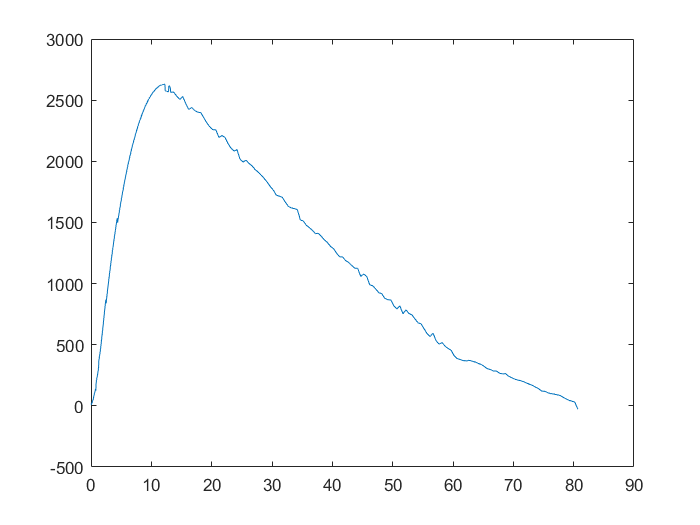

clf;
plot(data(:, 1), data(:, 2))

starting_pos = 0; %m
expected_velocity = 180; %m/s
expected_acceleration = 0; %m/s^2
alpha = .8;
beta = .8;
gamma = .8;
dt = .05;

pred_position = [starting_pos + expected_velocity * dt + expected_acceleration * dt ^ 2 / 2];
calc_position = [];
pred_velocity = [expected_velocity + expected_acceleration * dt]

pred_velocity = 180

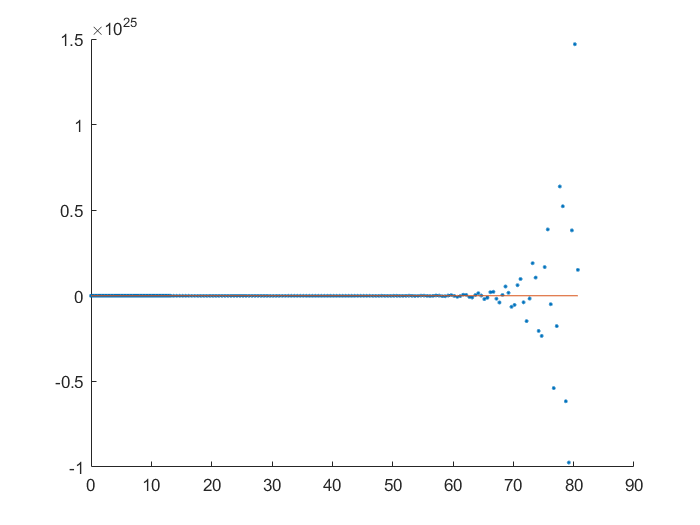

calc_velocity = [];
pred_acceleration = [expected_acceleration];
calc_acceleration = [];

for i = 1:size(data, 1)
    meas_position = data(i, 2);
    calc_position = [calc_position pred_position(end) + alpha * (meas_position - pred_position(end))];
    
    calc_velocity = [calc_velocity pred_velocity(end) + beta * (((meas_position - pred_position(end)) / dt))];
    calc_acceleration = [calc_acceleration pred_acceleration(end) + gamma * (((meas_position - pred_position(end)) / dt^2 / .5))];
    
    pred_position = [pred_position calc_position(end) + calc_velocity(end) * dt + calc_acceleration(end) * .5 * dt^2];
    pred_velocity = [pred_velocity calc_velocity(end) + calc_acceleration(end) * dt];
    pred_acceleration = [pred_acceleration calc_acceleration(end)];
end
clf;
hold on;

plot(data(:, 1), calc_position, '.');
plot(data(:, 1), data(:, 2));
hold off;

calculate percent errors

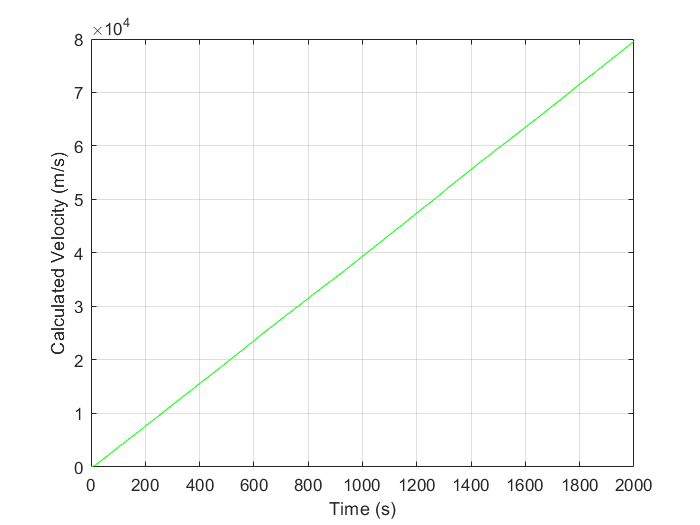

error_meas = (real_position - meas_position) ./ (meas_position) * 100;
error_calc = (real_position - calc_position) ./ (calc_position) * 100;


t = linspace(1,2000,2000);

figure(1);
hold on
grid on
plot(t, calc_velocity, 'g-');
ylabel('Calculated Velocity (m/s)')
xlabel('Time (s)')

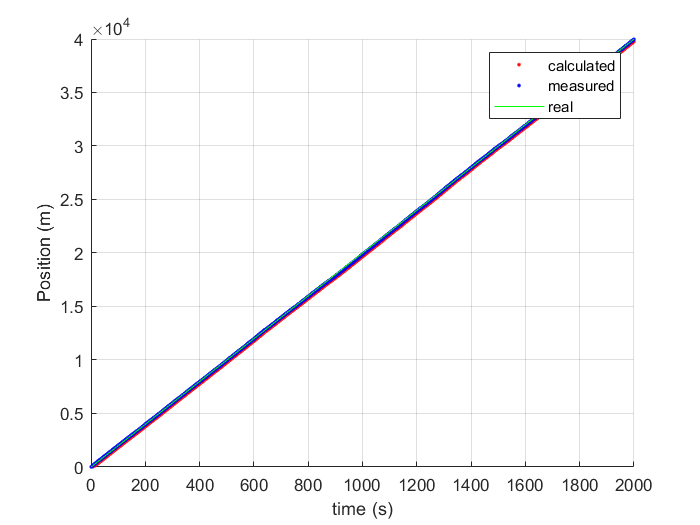


figure(2);
hold on
grid on
plot(t, calc_position, 'r.', 'DisplayName', 'calculated');
plot(t, meas_position, 'b.', 'DisplayName', 'measured');
plot(t, real_position, 'g-', 'DisplayName', 'real');
ylabel('Position (m)')
legend();
xlabel('time (s)')

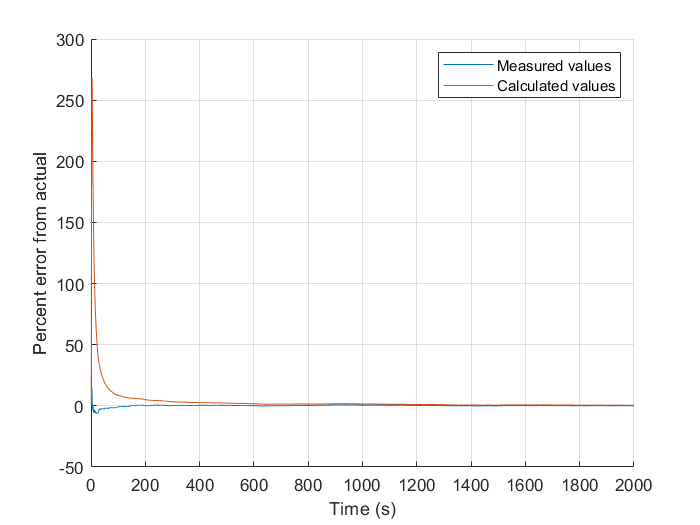


figure(3);
hold on
grid on
plot(t, error_meas, 'DisplayName', 'Measured values')
plot(t, error_calc, 'DisplayName', 'Calculated values')
ylabel('Percent error from actual');
xlabel('Time (s)');
legend();